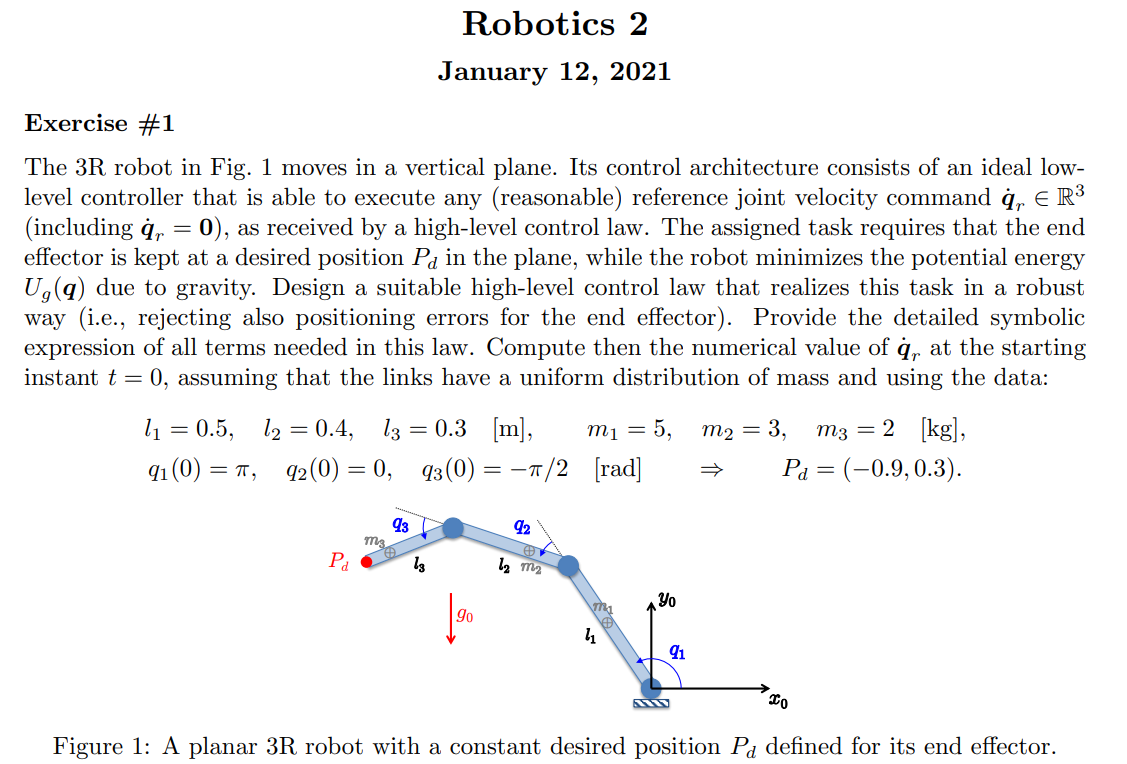

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% 

% 
% PC_EEShort.J
% PC_EEShort.f

% VarShortRobot.M
% angle_desired=[0,0]
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)

% 
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(PCVar.Pc, z.q, z.l, z.m, z.dc, z.g, z.isMotor)
% 

% U{1}
% PE_short
% g_q

% z.l_=[0.5,0.4,0.3]
% z.dc_=z.l_/2
% z.m_=[5,3,2]
% z.q_=[pi,0,-pi/2]
% to_replace=[z.l',z.dc',z.m',z.q',g0]
% to_replace_=[z.l_,z.dc_,z.m_,z.q_ ,9.8]
% f_=vpa(subs(f,to_replace,to_replace_))
% J_=vpa(subs(J,to_replace,to_replace_))
% J_ps_=vpa(subs(J_ps,to_replace,to_replace_))
% g_q_=vpa(subs(g_q,to_replace,to_replace_))
% 
% q_r_dot_= vpa(g_q_-J_ps_*J_*g_q_)


## Exercise 3

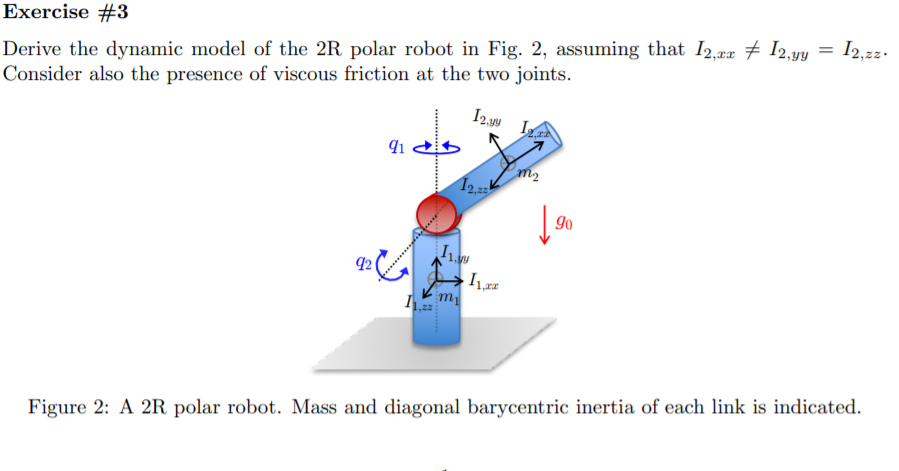

% % close all
% % % Lengths just to test
% % d1_=10;
% % d2_=10;
% % a2_=10;
% % % % De Luca's approach
% %  links = [
% %     Revolute('a', 0, 'alpha', pi/2 ,'d', 1);
% %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% % %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% %     ];
% % % 
% %  c600 = SerialLink(links);
% %  c600.teach([0 0],'view','x');
% % % c600.plot([0  pi/2 20 0],'view','x')
% % % clear

% 

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['rr';'zx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% % z.I=I;
% z.methodD=2%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
%             0       , z.l(2)  , 0   , q(2);]

% 
% %[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2_xyz(z)

% Pc
% % Trans.PPartial{1}
% vc
% simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))
% Ti(1)
% Ti(2)
% w
% M

% % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])
% [Msubs, dynamicParameters, aM] = getDynamicParameters3(M,z.q,[],2)

% Msubs
% dynamicParameters
% % 
% 
% % PC_EEShort.J
% % PC_EEShort.f

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

% [C,cac,Csubs,] = getCs(Msubs,z.q,z.q_dot)

% cac

% g_q
% U{:}

% F_v=sym('F',[2,1],'real')
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,g_q,F_v],q,[q_dot.',g0],2)
% [All, dynamicParamsReturn, a]= getDynamicParameters3([M,g_q,F_v],q,[q_dot;g0],2)

% 
% All

% %complete model
% M_subs_     =All(:,1:n)
% g_q_        =All(:,n+1)
% F_v_        =All(:,n+2)
% M_subs_*z.q_ddot+cac+g_q_+F_v_.*z.q_dot%=Tao

## 6

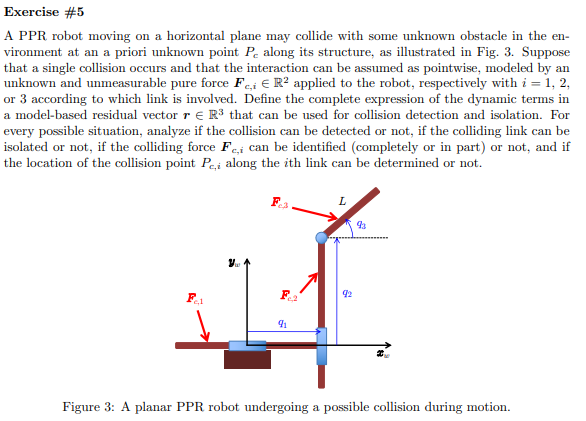

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0,1];
R2Robot=['ppr';'xyx';sigmaD]

R2Robot = 3×3 char array
    'ppr'
    'xyx'
    '  '


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;



% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
[Pc,vc,w,T,Ti,M] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$Pc = \left(\begin{array}{ccc} q_{1} & q_{1} & q_{1}+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\\ 0 & q_{2} & q_{2}+{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{ccc} {\dot{q}}_{1} & {\dot{q}}_{1} & {\dot{q}}_{1}-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & {\dot{q}}_{2} & {\dot{q}}_{2}+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & {\dot{q}}_{3} \end{array}\right)$$

$$T = \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right) & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)$$


[C,cac,Csubs,S] = getCs(M,z.q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


Pc

$$Pc = \left(\begin{array}{ccc} q_{1} & q_{1} & q_{1}+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\\ 0 & q_{2} & q_{2}+{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

M

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right) & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)$$

S

$$S = \left(\begin{array}{ccc} 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

% g_q

## get dinamyc paramters

% % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% % [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],1)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% [C,cac,Csubs,S1] = getCs(M,q,q_dot)
% % u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% % [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% %
% % Msubs = All(:,1:n)
% % gSubs = diag(All(:,n+1:2*n))
% % FSubs = All(:,2*n+1:end)
% [Md,Mtd,qt]  = getM_dot2(M, q, q_dot)

% [S0,S_] = getGenericS0(q,q_dot)
% S_(:,1)
% S0{1}
% % S0_=subs(S0{2},S_(:,1)',[q_dot(2),0]);
% S0_=subs(S0{1},S_(:,2)',[-z.m(2)*z.q_dot(1)*(z.dc(2)-z.q(2)),0]);
% S0_
% S2=S1+S0_
% S1
% Md
% simplify(Md-2*S1)
% simplify(Md-2*S2)

% % u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

**Collisions**

defining collisions link 1

% %
% % collide1=
rho=sym('rho',[2,1],'real')

$$rho = \left(\begin{array}{c} \rho_{1}\\ \rho_{2} \end{array}\right)$$

F=sym('F_',[3,1],'real')

$$F = \left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{3} \end{array}\right)$$

F_=[F(1),F(2),0]'

$$F\_ = \left(\begin{array}{c} F_{1}\\ F_{2}\\ 0 \end{array}\right)$$

z.collides=[struct('F',F_ ,'joint',1,'F_pos',rho(1)),
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',1,'F_pos',z.q(1)-rho(1)),
%             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
%             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
            ];
z.collides(1)

ans = struct with fields:
        F: [3×1 sym]
    joint: 1
    F_pos: rho1


computing colissions

z.prismatic_CoM_method=[2,2,1]

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0

[Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

% zout.g_q
zout.S

$$ans = \left(\begin{array}{ccc} 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

zout.J_c_collisions_{:}
zout.J_c_collisions{:}

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

zout.vc_collisions

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\\ 0\\ 0 \end{array}\right)$$

zout.Vc_T_dot_Fk

$$ans = F_{1}\,{\dot{q}}_{1}$$

zout.Tau_c

$$ans = \left(\begin{array}{c} F_{1}\\ 0\\ 0 \end{array}\right)$$

zout.r

$$ans = \left(\begin{array}{c} r_{1}\\ r_{2}\\ r_{3} \end{array}\right)$$

zout.p_r

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(m_{1}+m_{2}+m_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ {\dot{q}}_{2}\,\left(m_{2}+m_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ {\dot{q}}_{3}\,\left(m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) \end{array}\right)$$

zout.to_integrate

$$ans = \left(\begin{array}{c} r_{1}+\tau_{1}\\ r_{2}+\tau_{2}-g_{0}\,\left(m_{2}+m_{3}\right)\\ r_{3}+\tau_{3}-{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% 

Defining collisions link 2

%
% collide1=
rho=sym('rho',[2,1],'real')

$$rho = \left(\begin{array}{c} \rho_{1}\\ \rho_{2} \end{array}\right)$$

% F_0=sym('F_0','real');
F=sym('F_',[3,1],'real')

$$F = \left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{3} \end{array}\right)$$

% F_=[0,F(2),0]'
z.collides=[struct('F',F ,'joint',2,'F_pos',rho(2)),
%             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
%             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
            ];
z.collides(1)

ans = struct with fields:
        F: [3×1 sym]
    joint: 2
    F_pos: rho2


Computing colissions on link 2

z.prismatic_CoM_method=[2,2,1]

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0

[Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Vc\_T\_dot\_Fk = F_{1}\,{\dot{q}}_{1}+F_{2}\,{\dot{q}}_{2}$$

$$Tau\_c = \left(\begin{array}{c} F_{1}\\ F_{2}\\ 0 \end{array}\right)$$

>> Getting  the Christoffel’sym. Might take a while...
*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccccccccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{3}\right) & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$PE = g_{0}\,\left(m_{2}\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}+m_{3}\,q_{2}+{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)$$

$$PE\_short = g_{0}\,\left(m_{2}\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}+m_{3}\,q_{2}+{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)$$

$$g\_q\_short = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{3}\right)\\ {\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


$$Pc = \left(\begin{array}{ccc} q_{1}-{\mathrm{dc}}_{1} & q_{1} & q_{1}+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\\ 0 & q_{2}-{\mathrm{dc}}_{2} & q_{2}+{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{ccc} {\dot{q}}_{1} & {\dot{q}}_{1} & {\dot{q}}_{1}-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & {\dot{q}}_{2} & {\dot{q}}_{2}+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & {\dot{q}}_{3} \end{array}\right)$$

$$T = \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right) & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: (I3*q_dot_3^2)/2 + (m1*q_dot_1^2)/2 + (m2*(q_dot_1^2 + q_dot_2^2))/2 + (m3*(dc3^2*q_dot_3^2 - 2*s3*dc3*q_dot_1*q_dot_3 + 2*c3*dc3*q_dot_2*q_dot_3 + q_dot_1^2 + q_dot_2^2))/2
    Ti: [(m1*q_dot_1^2)/2    (m2*(q_dot_1^2 + q_dot_2^2))/2    (I3*q_dot_3^2)/2 + (m3*(dc3^2*q_dot_3^2 - 2*s3*dc3*q_dot_1*q_dot_3 + 2*c3*dc3*q_dot_2*q_dot_3 + q_dot_1^2 + q_dot_2^2))/2]
     M: [3×3 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×3 sym]
               TPartial: {[4×4 sym]  [4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×3 sym]
    Jacobian_dot_PTotal: [3×3 sym]
               PPartial: {[3×1 sym]  [3×1 sym]  [3×1 sym]}
                     Pc: [3×3 sym]
                RTotali: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
           ThetaPartial: [3×1 sym]
             ThetaTotal: q_3
                     vc: [3×3 sym]
                      w: [3×3 sym]
                      T: (I3*q_dot_3^2)/2 + (m1*q_dot_1^2)/2 + (m3*(dc3^2*q_dot_3^2 - 2*sin(q_3)*dc3*q_dot_1*q_dot_3 + 2*cos(q_3)*dc3*q_dot_2*q_dot_3 + q_dot_1^2 + q_dot_2^2))/2 + (m2*(q_dot_1^2 + q_dot_2^2))/2
                     Ti: [(m1*q_dot_1^2)/2    (m2*(q_dot_1^2 + q_dot_2^2))/2    (I3*q_dot_3^2)/2 + (m3*(dc3^2*q_dot_3^2 - 2*sin(q_3)*dc3*q_dot_1*q

zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
      Pc_collisions: [3×1 sym]
      vc_collisions: [3×1 sym]
     J_c_collisions: {[3×3 sym]}
        Vc_T_dot_Fk: F_1*q_dot_1 + F_2*q_dot_2
              Tau_c: [3×1 sym]
                p_r: [3×1 sym]
                tau: [3×1 sym]
                  r: [3×1 sym]
                P_0: [3×1 sym]
       to_integrate: [3×1 sym]


% zout.g_q
zout.S

$$ans = \left(\begin{array}{ccc} 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

zout.J_c_collisions_{:}
zout.J_c_collisions{:}

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$

zout.vc_collisions

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ 0 \end{array}\right)$$

zout.Vc_T_dot_Fk

$$ans = F_{1}\,{\dot{q}}_{1}+F_{2}\,{\dot{q}}_{2}$$

zout.Tau_c

$$ans = \left(\begin{array}{c} F_{1}\\ F_{2}\\ 0 \end{array}\right)$$

zout.r

$$ans = \left(\begin{array}{c} r_{1}\\ r_{2}\\ r_{3} \end{array}\right)$$

zout.p_r

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(m_{1}+m_{2}+m_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ {\dot{q}}_{2}\,\left(m_{2}+m_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ {\dot{q}}_{3}\,\left(m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) \end{array}\right)$$

zout.to_integrate

$$ans = \left(\begin{array}{c} r_{1}+\tau_{1}\\ r_{2}+\tau_{2}-g_{0}\,\left(m_{2}+m_{3}\right)\\ r_{3}+\tau_{3}-{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% 

Defining collisions link 3

%
% collide1=
rho=sym('rho',[3,1],'real')

$$rho = \left(\begin{array}{c} \rho_{1}\\ \rho_{2}\\ \rho_{3} \end{array}\right)$$

% F_0=sym('F_0','real');
F=sym('F_',[3,1],'real')

$$F = \left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{3} \end{array}\right)$$

% F_=[0,F(2),0]'
z.collides=[struct('F',F ,'joint',3,'F_pos',rho(3)),
%             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
%             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
            ];
z.collides(1)

ans = struct with fields:
        F: [3×1 sym]
    joint: 3
    F_pos: rho3


Computing colissions on link 3

z.prismatic_CoM_method=[2,2,1]

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0

[Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Vc\_T\_dot\_Fk = F_{2}\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\,\rho_{3}\,\cos\left(q_{3}\right)\right)+F_{1}\,\left({\dot{q}}_{1}-{\dot{q}}_{3}\,\rho_{3}\,\sin\left(q_{3}\right)\right)$$

$$Tau\_c = \left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{2}\,\rho_{3}\,\cos\left(q_{3}\right)-F_{1}\,\rho_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

>> Getting  the Christoffel’sym. Might take a while...
*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccccccccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{3}\right) & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$PE = g_{0}\,\left(m_{2}\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}+m_{3}\,q_{2}+{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)$$

$$PE\_short = g_{0}\,\left(m_{2}\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}+m_{3}\,q_{2}+{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)$$

$$g\_q\_short = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{3}\right)\\ {\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))


$$Pc = \left(\begin{array}{ccc} q_{1}-{\mathrm{dc}}_{1} & q_{1} & q_{1}+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\\ 0 & q_{2}-{\mathrm{dc}}_{2} & q_{2}+{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{ccc} {\dot{q}}_{1} & {\dot{q}}_{1} & {\dot{q}}_{1}-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & {\dot{q}}_{2} & {\dot{q}}_{2}+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & {\dot{q}}_{3} \end{array}\right)$$

$$T = \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ -{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right) & {\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: (I3*q_dot_3^2)/2 + (m1*q_dot_1^2)/2 + (m2*(q_dot_1^2 + q_dot_2^2))/2 + (m3*(dc3^2*q_dot_3^2 - 2*s3*dc3*q_dot_1*q_dot_3 + 2*c3*dc3*q_dot_2*q_dot_3 + q_dot_1^2 + q_dot_2^2))/2
    Ti: [(m1*q_dot_1^2)/2    (m2*(q_dot_1^2 + q_dot_2^2))/2    (I3*q_dot_3^2)/2 + (m3*(dc3^2*q_dot_3^2 - 2*s3*dc3*q_dot_1*q_dot_3 + 2*c3*dc3*q_dot_2*q_dot_3 + q_dot_1^2 + q_dot_2^2))/2]
     M: [3×3 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×3 sym]
               TPartial: {[4×4 sym]  [4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×3 sym]
    Jacobian_dot_PTotal: [3×3 sym]
               PPartial: {[3×1 sym]  [3×1 sym]  [3×1 sym]}
                     Pc: [3×3 sym]
                RTotali: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
           ThetaPartial: [3×1 sym]
             ThetaTotal: q_3
                     vc: [3×3 sym]
                      w: [3×3 sym]
                      T: (I3*q_dot_3^2)/2 + (m1*q_dot_1^2)/2 + (m3*(dc3^2*q_dot_3^2 - 2*sin(q_3)*dc3*q_dot_1*q_dot_3 + 2*cos(q_3)*dc3*q_dot_2*q_dot_3 + q_dot_1^2 + q_dot_2^2))/2 + (m2*(q_dot_1^2 + q_dot_2^2))/2
                     Ti: [(m1*q_dot_1^2)/2    (m2*(q_dot_1^2 + q_dot_2^2))/2    (I3*q_dot_3^2)/2 + (m3*(dc3^2*q_dot_3^2 - 2*sin(q_3)*dc3*q_dot_1*q

zout = struct with fields:
    J_c_collisions_: {}
                  C: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                cac: [3×1 sym]
              Csubs: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                  S: [3×3 sym]
                g_q: [3×1 sym]
                 PE: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
                  U: {0  -g0*m2*(dc2 - q_2)  g0*m3*(q_2 + dc3*sin(q_3))}
          g_q_short: [3×1 sym]
           PE_short: g0*(m2*q_2 - dc2*m2 + m3*q_2 + dc3*m3*sin(q_3))
      Pc_collisions: [3×1 sym]
      vc_collisions: [3×1 sym]
     J_c_collisions: {[3×3 sym]}
        Vc_T_dot_Fk: F_2*(q_dot_2 + q_dot_3*rho3*cos(q_3)) + F_1*(q_dot_1 - q_dot_3*rho3*sin(q_3))
              Tau_c: [3×1 sym]
                p_r: [3×1 sym]
                tau: [3×1 sym]
                  r: [3×1 sym]
                P_0: [3×1 sym]
       to_integrate: [3×1 sym]


% zout.g_q
zout.S

$$ans = \left(\begin{array}{ccc} 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

zout.J_c_collisions_{:}
zout.J_c_collisions{:}

$$ans = \left(\begin{array}{ccc} 1 & 0 & -\rho_{3}\,\sin\left(q_{3}\right)\\ 0 & 1 & \rho_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

zout.vc_collisions

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}-{\dot{q}}_{3}\,\rho_{3}\,\sin\left(q_{3}\right)\\ {\dot{q}}_{2}+{\dot{q}}_{3}\,\rho_{3}\,\cos\left(q_{3}\right)\\ 0 \end{array}\right)$$

zout.Vc_T_dot_Fk

$$ans = F_{2}\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\,\rho_{3}\,\cos\left(q_{3}\right)\right)+F_{1}\,\left({\dot{q}}_{1}-{\dot{q}}_{3}\,\rho_{3}\,\sin\left(q_{3}\right)\right)$$

zout.Tau_c

$$ans = \left(\begin{array}{c} F_{1}\\ F_{2}\\ \rho_{3}\,\left(F_{2}\,\cos\left(q_{3}\right)-F_{1}\,\sin\left(q_{3}\right)\right) \end{array}\right)$$

zout.r

$$ans = \left(\begin{array}{c} r_{1}\\ r_{2}\\ r_{3} \end{array}\right)$$

zout.p_r

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(m_{1}+m_{2}+m_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ {\dot{q}}_{2}\,\left(m_{2}+m_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ {\dot{q}}_{3}\,\left(m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) \end{array}\right)$$

zout.to_integrate

$$ans = \left(\begin{array}{c} r_{1}+\tau_{1}\\ r_{2}+\tau_{2}-g_{0}\,\left(m_{2}+m_{3}\right)\\ r_{3}+\tau_{3}-{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% 
% 